## **パラメータ定義**

clear;

syms t theta(t) phi(t) tau g
% 振り子
syms Mp Jp l u_1
% タイヤ
syms Mw Jw a u_2

## 一般化座標ベクトル定義

q = [theta(t); phi(t)]

$$q = \left(\begin{array}{c} \theta \left(t\right)\\ \varphi \left(t\right) \end{array}\right)$$

dq = diff(q,t)

$$dq = \left(\begin{array}{c} \frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

ddq = diff(dq,t)

$$ddq = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}\right)$$

% 一般化外力
force = [0; tau]

$$force = \left(\begin{array}{c} 0\\ \tau \end{array}\right)$$

## 直交座標変換

% タイヤの並進方向
xw = a*(q(1)+q(2));

% 全微分を用いた文字式の常微分
% == diff(xw,t);
dxw = diff(xw, q(1))*dq(1) + diff(xw, q(2))*dq(2)

$$dxw = a\,\frac{\partial }{\partial t}\varphi \left(t\right)+a\,\frac{\partial }{\partial t}\theta \left(t\right)$$


% 振子の直交座標表記
xp = l*sin(q(1)) + xw;
yp = l*cos(q(1));

% 振子直交座標の微分
dxp = diff(xp,q(1))*dq(1) + diff(xp,q(2))*dq(2)

$$dxp = a\,\frac{\partial }{\partial t}\varphi \left(t\right)+\left(a+l\,\cos\left(\theta \left(t\right)\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)$$

dyp = diff(yp, q(1))*dq(1) + diff(yp,q(2))*dq(2)

$$dyp = -l\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)$$

## 振子のエネルギー

% 並進エネルギー
Kpt = 1/2 * Mp * ((dxp^2) + (dyp^2));

% 回転エネルギー
Kpr = 1/2 * Jp * dq(1)^2;

% 位置エネルギー
Up = Mp * g * (l+yp);

% 損失エネルギー(空気摩擦)
Dp = 1/2 * u_1 * dq(1)^2;


## タイヤのエネルギー

% 並進エネルギー
Kwt = 1/2 * Mw * dxw^2;

% 回転エネルギー
Kwr = 1/2 * Jw * (dq(1) + dq(2))^2;

% 位置エネルギー

% 損失エネルギー(空気摩擦)
Dw = 1/2 * u_2 *dq(2)^2;


## ラグランジュの運動方程式

% エネルギーの総和を求める
K = Kpt + Kpr + Kwt + Kwr;
U = Up;

% 損失エネルギーDをベクトル形式に
D = [Dp; Dw];

% ラグラジアン
L = K-U;

% 状態変数分forループを回すので母数を決める:N
N = length(q);

% メモリ確保
dLq = sym('dLq', [2 1]);
ddLq = sym('ddLq', [2 1]);
eq = sym('eq', [2 1]);

% ラグランジュの運動方程式を立てる
for i = 1:N
    dLq(i) = diff(L,dq(i));
    temp = 0;
    for j = 1:N
        temp = temp + diff(dLq(i),dq(j))*ddq(j) + diff(dLq(i),q(j))*dq(j);
    end
    ddLq(i) = temp;

    eq(i) = ddLq(i) - diff(L, q(i)) + diff(D(i),dq(i))== force(i);
end
simplify(eq(1))

$$ans = u_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+\left(\mathrm{Jp}+\mathrm{Jw}+\mathrm{Mp}\,a^{2}+\mathrm{Mw}\,a^{2}+\mathrm{Mp}\,l^{2}+2\,\mathrm{Mp}\,a\,l\,\cos\left(\theta \left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\left(\mathrm{Jw}+\mathrm{Mp}\,a^{2}+\mathrm{Mw}\,a^{2}+\mathrm{Mp}\,a\,l\,\cos\left(\theta \left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\mathrm{Mp}\,a\,l\,\sin\left(\theta \left(t\right)\right)\,\left(\frac{\partial }{\partial t}\varphi \left(t\right)+\frac{\partial }{\partial t}\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)=\mathrm{Mp}\,l\,\sin\left(\theta \left(t\right)\right)\,\left(2\,a\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+a\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+g\right)$$

simplify(eq(2))

$$ans = \mathrm{Mp}\,a\,l\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\tau =\left(\mathrm{Jw}+\mathrm{Mp}\,a^{2}+\mathrm{Mw}\,a^{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\left(\mathrm{Jw}+\mathrm{Mw}\,a^{2}+\mathrm{Mp}\,a\,\left(a+l\,\cos\left(\theta \left(t\right)\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+u_{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

## 数値積分でシミュレーション

パラメータ

% syms t theta(t) phi(t) tau(t) g
% % 振り子
% syms Mp Jp l u_1
% % タイヤ
% syms Mw Jw a u_2

g = 9.81;

Mp = 0.5;
Jp = 0.1;
l = 0.5;
u_1 = 0.24;

Mw = 0.3;
Jw = 1;
a = 0.3;
u_2 = 0.1;

% 一般化外力
tau = 0;


## 状態ベクトル表示にする

## odeToVectorFieldで状態変数=へ整理

% パラメータを代入
eqn_1 = subs(eq(1));
eqn_2 = subs(eq(2));


[V,State] = odeToVectorField(eqn_1, eqn_2);
V

$$V = \begin{array}{l} \left(\begin{array}{c} Y_{2}\\ -\frac{-3750\,{\cos\left(Y_{3}\right)}^{2}\,\sin\left(Y_{3}\right)\,{Y_{4}}^{2}+5000\,Y_{2}\,{\cos\left(Y_{3}\right)}^{2}-2250\,\cos\left(Y_{3}\right)\,\sin\left(Y_{3}\right)\,{Y_{4}}^{2}+73575\,\cos\left(Y_{3}\right)\,\sin\left(Y_{3}\right)-7200\,\cos\left(Y_{3}\right)\,Y_{4}+6000\,Y_{2}\,\cos\left(Y_{3}\right)-3750\,{\sin\left(Y_{3}\right)}^{3}\,{Y_{4}}^{2}+5000\,Y_{2}\,{\sin\left(Y_{3}\right)}^{2}-3000\,\sin\left(Y_{3}\right)\,{Y_{4}}^{2}+1051632\,\sin\left(Y_{3}\right)-102912\,Y_{4}+46880\,Y_{2}}{10\,\sigma_{1}}\\ Y_{4}\\ \frac{-1125\,\cos\left(Y_{3}\right)\,\sin\left(Y_{3}\right)\,{Y_{4}}^{2}-51456\,Y_{4}+525816\,\sin\left(Y_{3}\right)+1500\,\cos\left(Y_{3}\right)\,Y_{2}+21440\,Y_{2}}{5\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5135\,{\cos\left(Y_{3}\right)}^{2}+5360\,{\sin\left(Y_{3}\right)}^{2}+4288 \end{array}$$


solveHandler = matlabFunction(V, 'Vars',{'t', 'Y'});
State

$$State = \left(\begin{array}{c} \varphi \\ \mathrm{Dphi}\\ \theta \\ \mathrm{Dtheta} \end{array}\right)$$

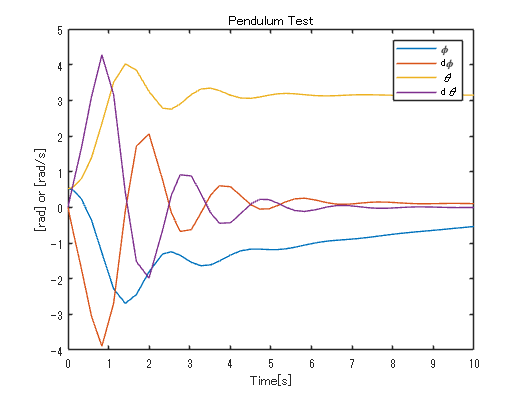

% 初期条件
initCond = [pi/6 0 pi/6 0];

% 時間幅
TimeLentgh = [0 10];

% 4次のルンゲクッタ法で数値積分
% 要素xに時間が、yに各状態変数の数値解が入っている
sols = ode45(solveHandler,TimeLentgh,initCond);

% グラフ表示
plot(sols.x,sols.y)
legend('\phi', 'd\phi', '\theta', 'd\theta')
title('Pendulum Test')
xlabel('Time[s]')
ylabel('[rad] or [rad/s]')